# Examples of Uncertainty Propagation

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES. The author thanks Joe Klebba for developing the toolbox for uncertainty propagation in Matlab.

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter1/Uncertainty'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction 

This notebook provides introduction to uncertainty propagation through several simple models. Uncertainty Quantification (UQ) aims at developing rigorous methods to characterize the impact of  ”limited knowledge” on quantities of interest.

## Example 1 Uncertainty of corellated variables

 Let us define a ratio R of AC currents obtained from a photodetector after emitting red and infrared light as: 


$$R=I_R/I_{IR}

$$


Assume the AC currents at the photodiode obtained after emitting red ( ) and infrared ( ) light are measured with the standard deviation of 0.5  . The values of   and   are  and  Let us assume that the measurements are correlated, and that the correlation coefficient is  = 0.7. What is the uncertainty of the ratio R? Let us assume that the  current follow normal distribution. Also, the distribution of R obtain  after dividing the random variable that follow normal distribution will  be also normal.

*Solution:*

*Method 1 Perturbation*

I_R=10; I_IR=20;
u_R=0.5; u_IR=0.5;
corrMatrix=[1 0.7; 0.7 1];
R = @(I_R,I_IR)I_R./I_IR;

[uncertCD,valCD]=propUncertCD(R,[I_R I_IR],[u_R u_IR],corrMatrix)

uncertCD = 0.0185

valCD = 0.5000

%Computation based on the formula from the text book
un_R=sqrt((u_R*1/I_IR)^2+(-u_IR*I_R/I_IR^2)^2-2*corrMatrix(1,2)*u_R*u_IR*I_R/I_IR^3)

un_R = 0.0185

*Method 2 Monte Carlo*

The same result  =0.0185 can be obtained using Monte Carlo sampling. First, we need to sample  from two-dimensional multivariate Gaussian distribution and obtain  correlated samples  and   for   where   is the number of Monte Carlo samples. We are using M=100,000 samples. Then, these samples are passed through the function  . Values   are fitted to a normal distribution and confidence intervals are  computed. The solution in Matlab is shown in the book web page.

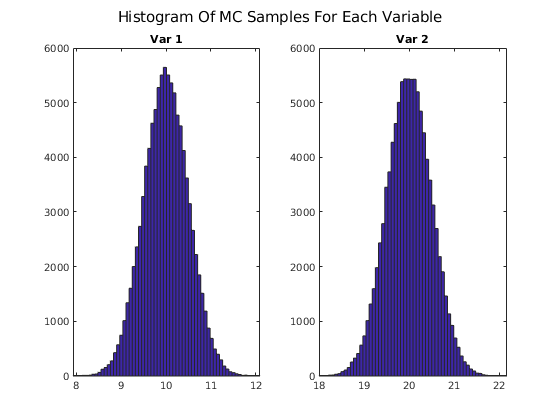

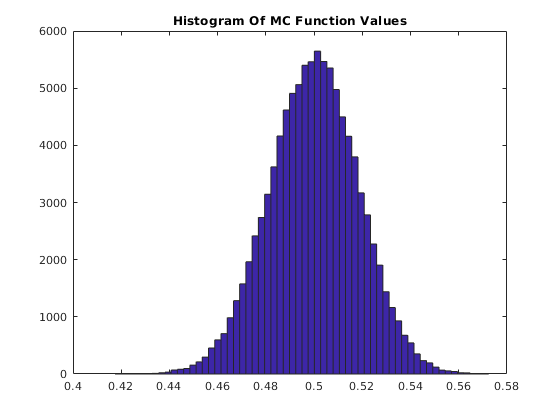

% Monte Carlo computation based on the method proposed by Joe Klebba 
[CI, funcVal, MCfuncVals, MCsamples]=propUncertMC(R,{{'Corr',{{I_R u_R};{I_IR u_IR}},corrMatrix}},100000,'varHist',60,'hist',60);

uncertMC = (CI(2)-CI(1))/2

uncertMC = 0.0184

valCD

valCD = 0.5000

% Monte Carlo computation based on the method from the text book
Cov=[u_R^2 corrMatrix(1,2)*u_R*u_IR; corrMatrix(1,2)*u_R*u_IR u_IR^2]

Cov =     0.2500    0.1750
    0.1750    0.2500


rng('default')  % For reproducibility
MvRnd = mvnrnd([I_R I_IR],Cov,100000);

MCfuncVals1=R(MvRnd(:,1),MvRnd(:,2));
pd = fitdist(MCfuncVals1,'Normal');
ci = paramci(pd,'Alpha',.33);
ci(2,2)

ans = 0.0186

## Example 2 Uncertainty based on GUM

a.  For a transducer with the following calibration curve, y = bx, estimate the expanded uncertainty for x = 5.00 , if b =1 with Ub =0.01 and   =0.05 at 95% confidence. Assume that all variables follow normal  distribution. Please note that we did not introduce units here and that  we assume that all the values are relative. 

b.  Compute the expanded uncertainty at 99% confidence.

*Solution:*

clear all
x=5; u_x=0.05/2;
b=1; u_b=0.01/2;
y=@(x,b)x.*b;
[uncertCD,valCD]=propUncertCD(y,[x b],[u_x u_b])

uncertCD = 0.0354

valCD = 5

U_95=uncertCD*2

U_95 = 0.0707

U_99=uncertCD*3

U_99 = 0.1061

% Calculation from the textbook
u_y=sqrt((x*u_b)^2+(b*u_x)^2)

u_y = 0.0354


[CI,valMC]=propUncertMC(y,{{x u_x};{b u_b}},100000);
uncertMC = (CI(2)-CI(1))/2

uncertMC = 0.0352

valMC

valMC = 4.9997

% Uncertainty can be directly computed to the desired level
[CI,valMC]=propUncertMC(y,{{x u_x};{b u_b}},100000,'CI',0.99);
uncertMC = (CI(2)-CI(1))/2

uncertMC = 0.0913

valMC

valMC = 4.9990

## Example 3 Combination of custom and normal distribution

Here, we will consider and example in which the data that is coming from a normal distribution  and is quantized using ADC converter with the resulution of 8 bits and the range of 5 V. 


n=100000;
%x_data = unifrnd(3,4,1,15);
x = normrnd(1,0.01,n,1);
ADC_res=5/2^8;
u_ADC=ADC_res/sqrt(12); % standard uncertainty for the "rounding" ADC
% Uncertainty in the measurements of x is Type A uncertainty while ADC
% converter uncertainty is type B. The total uncertainty based on GUM is:
u_total=sqrt(u_ADC^2+0.01^2)

u_total = 0.0115


f = @(x,u)x+u;
[CI,valMC]=propUncertMC(f,{{'Custom',x};{'uniform',0,ADC_res}},n);
uncertMC = (CI(2)-CI(1))/2

uncertMC = 0.0115

valMC

valMC = 1.0102